# Parte 1: Modulación AM DSB-SC de los tonos

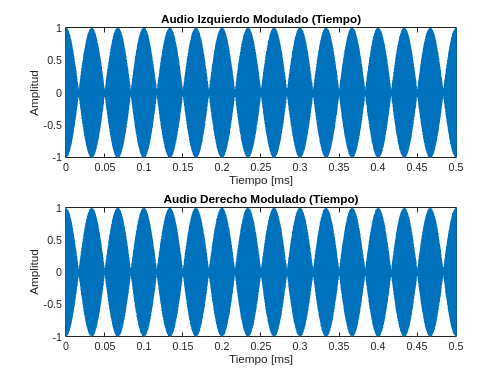

clear; close all; clc;

% Parámetros de simulación
fs = 100e6;        % Frecuencia de muestreo (100 MHz)
t = 0:1/fs:1e-3;   % Tiempo de 1 ms de duración

% Parámetros de las señales
f_audioL = 15e3;   % 15 kHz - Audio Izquierdo
f_audioR = 15e3;   % 15 kHz - Audio Derecho
f_cL = 5e6;        % 5 MHz - Portadora Audio Izquierdo
f_cR = 4.8e6;      % 4.8 MHz - Portadora Audio Derecho

% Generación de las señales de audio
audioL = cos(2*pi*f_audioL*t);
audioR = cos(2*pi*f_audioR*t);

% Generación de las portadoras
carrierL = cos(2*pi*f_cL*t);
carrierR = cos(2*pi*f_cR*t);

% Modulación DSB-SC (Producto señal × portadora)
modulatedL = audioL .* carrierL;
modulatedR = audioR .* carrierR;

%% Graficar señales en el tiempo
figure;
subplot(2,1,1);
plot(t*1e3, modulatedL);
title('Audio Izquierdo Modulado (Tiempo)');
xlabel('Tiempo [ms]');
ylabel('Amplitud');
xlim([0 0.5]);

subplot(2,1,2);
plot(t*1e3, modulatedR);
title('Audio Derecho Modulado (Tiempo)');
xlabel('Tiempo [ms]');
ylabel('Amplitud');
xlim([0 0.5]);

## Graficar espectros de audios

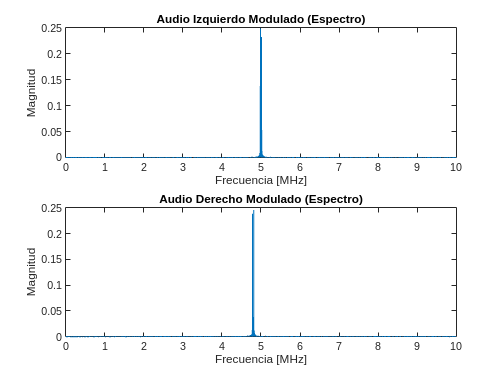


nfft = 2^nextpow2(length(t)); % Mejor tamaño para la FFT

f = linspace(-fs/2, fs/2, nfft);

% FFT y centrado en 0 Hz
ModL_fft = abs(fftshift(fft(modulatedL, nfft)))/length(t);
ModR_fft = abs(fftshift(fft(modulatedR, nfft)))/length(t);

figure;
subplot(2,1,1);
plot(f/1e6, ModL_fft);
title('Audio Izquierdo Modulado (Espectro)');
xlabel('Frecuencia [MHz]');
ylabel('Magnitud');
xlim([0 10]);

subplot(2,1,2);
plot(f/1e6, ModR_fft);
title('Audio Derecho Modulado (Espectro)');
xlabel('Frecuencia [MHz]');
ylabel('Magnitud');
xlim([0 10]);

## Parte 2: Generación del Video Simulado y Pulso de Sincronía

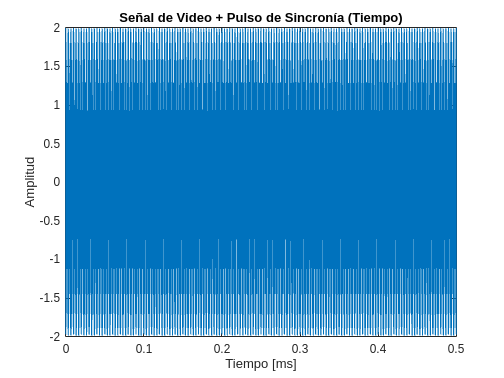



% Parámetros de las señales
f_video = 4.2e6;          % 4.2 MHz - Video
f_sync = 4.5e6;           % 4.5 MHz - Pulso de sincronía

% Generación de señales
video_signal = cos(2*pi*f_video*t);
sync_pulse = cos(2*pi*f_sync*t);

% Suma de video + sincronizador
video_total = video_signal + sync_pulse;

%% Graficar señal de video en el tiempo
figure;
plot(t*1e3, video_total);
title('Señal de Video + Pulso de Sincronía (Tiempo)');
xlabel('Tiempo [ms]');
ylabel('Amplitud');
xlim([0 0.5]);

## Graficar espectro del video

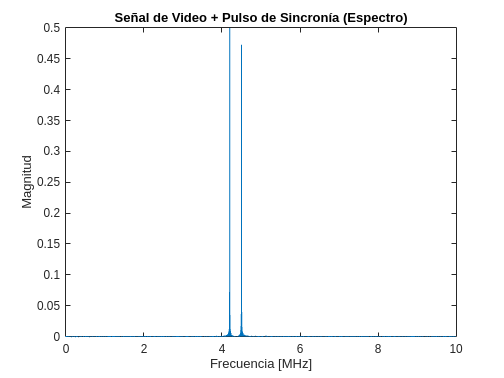


Video_fft = abs(fftshift(fft(video_total, nfft)))/length(t);

figure;
plot(f/1e6, Video_fft);
title('Señal de Video + Pulso de Sincronía (Espectro)');
xlabel('Frecuencia [MHz]');
ylabel('Magnitud');
xlim([0 10]);

## Parte 3: Multiplexación (FDM) - Empaquetado de frecuencias

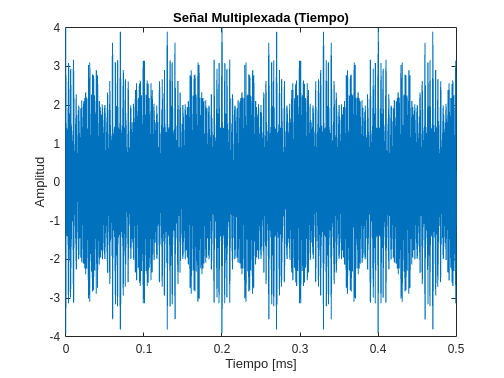


% Sumamos todas las señales moduladas
multiplexed_signal = modulatedL + modulatedR + video_total;

%%Graficar multiplexado en el tiempo
figure;
plot(t*1e3, multiplexed_signal);
title('Señal Multiplexada (Tiempo)');
xlabel('Tiempo [ms]');
ylabel('Amplitud');
xlim([0 0.5]);

## Graficar espectro multiplexado

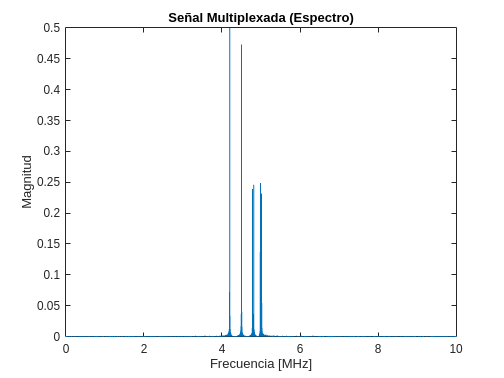


Multiplexed_fft = abs(fftshift(fft(multiplexed_signal, nfft)))/length(t);

figure;
plot(f/1e6, Multiplexed_fft);
title('Señal Multiplexada (Espectro)');
xlabel('Frecuencia [MHz]');
ylabel('Magnitud');
xlim([0 10]);

## Parte 4: Modulación FM usando función fmmod

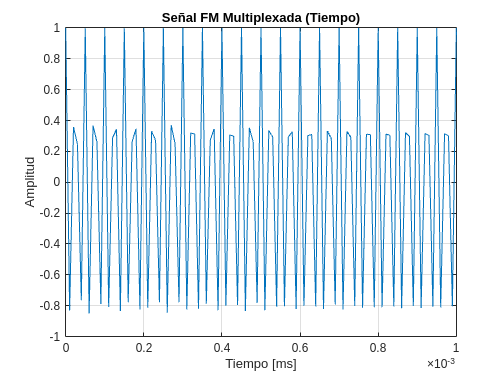

%% Parte 4: Modulación FM usando función fmmod

% Parámetros
Ac = 1;               % Amplitud de la portadora
fc_FM = 40e6;         % Frecuencia de portadora
freq_dev = 75e3;      % Desviación de frecuencia típica FM comercial (75 kHz)

% Aseguramos que multiplexed_signal sea vector fila
multiplexed_signal = reshape(multiplexed_signal, 1, []); 

% Modulación FM usando fmmod
s_FM = Ac * fmmod(multiplexed_signal, fc_FM, fs, freq_dev);

% Graficar en tiempo
figure;
plot(t*1e3, s_FM);
title('Señal FM Multiplexada (Tiempo)');
xlabel('Tiempo [ms]');
ylabel('Amplitud');
xlim([0 0.001]);
grid on;

## Calcular y graficar espectro de la señal FM

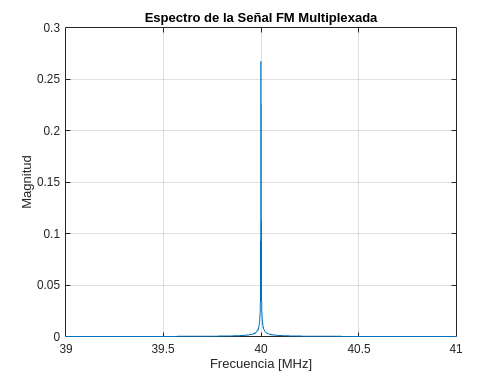

nfft = 2^16; % Número fijo de puntos para la FFT

% Asegurarse de que s_FM sea un vector fila
s_FM = s_FM(:)'; % Convertir a fila si es columna

% Si s_FM tiene menos de nfft puntos, completamos con ceros
if length(s_FM) < nfft
    s_FM = [s_FM, zeros(1, nfft - length(s_FM))];
end

% Generar ventana Hamming del mismo tamaño que s_FM
window = hamming(length(s_FM)).';

% Aplicar ventana y calcular FFT
y = window .* s_FM;                % Ahora ambos son vectores filas del mismo largo
Y = fft(y, nfft);                  % Hacer FFT
Y = fftshift(Y);                   % Centrar en 0 Hz
Y = abs(Y) / nfft;                 % Magnitud normalizada

% Vector de frecuencias
f = (-fs/2 : fs/nfft : fs/2 - fs/nfft);

% Graficar
figure;
plot(f/1e6, Y);
title('Espectro de la Señal FM Multiplexada');
xlabel('Frecuencia [MHz]');
ylabel('Magnitud');
xlim([39 41]); % Visualización centrada en 40 MHz
grid on;

## Parte 5 Demodulación

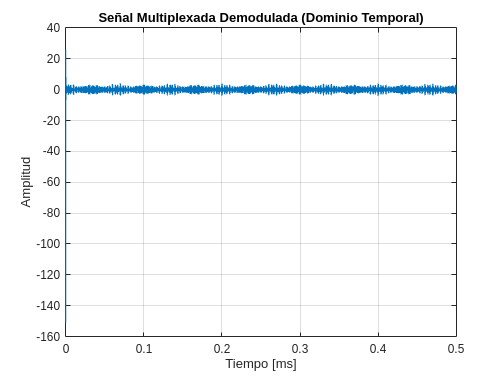

% Demodulación FM
multiplexed_demod = fmdemod(s_FM, fc_FM, fs, freq_dev);

% Graficar en tiempo
figure;
plot(t*1e3, multiplexed_demod);
title('Señal Multiplexada Demodulada (Dominio Temporal)');
xlabel('Tiempo [ms]');
ylabel('Amplitud');
xlim([0 0.5]);
grid on;

## Graficar espectro de la señal demodulada

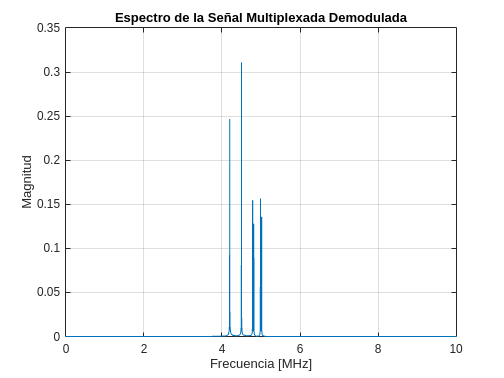

% Parámetros FFT
nfft = 2^16; % Número fijo de puntos para una buena resolución
window = hamming(length(multiplexed_demod)); % Ventana Hamming para reducir leakage

% Aplicar ventana y calcular FFT
y = window' .* multiplexed_demod; % Elemento a elemento
Y = fftshift(fft(y, nfft));        % FFT y centrado en 0 Hz
Y = abs(Y) / nfft;                 % Magnitud normalizada

% Vector de frecuencias
f = (-fs/2 : fs/nfft : fs/2 - fs/nfft); % Frecuencias (en Hz)

% Graficar
figure;
plot(f/1e6, Y); % En MHz
title('Espectro de la Señal Multiplexada Demodulada');
xlabel('Frecuencia [MHz]');
ylabel('Magnitud');
xlim([0 10]); % Rango de interés (ajustable)
grid on;